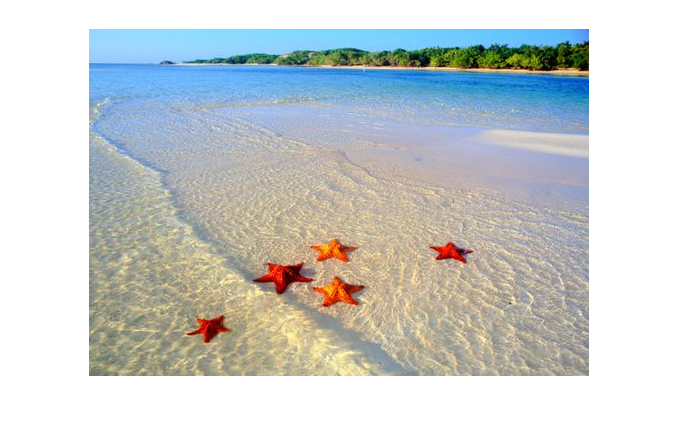

im = imread("images\starfish_5.jpg");
imshow(im)

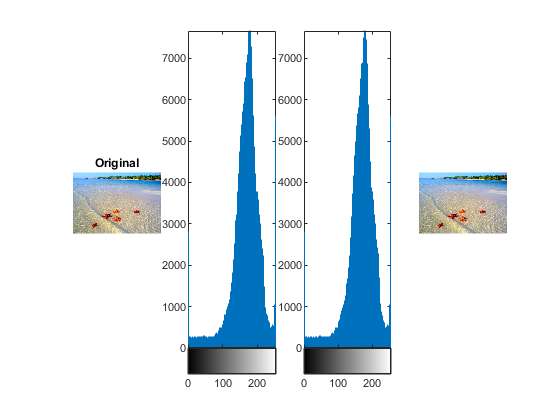

spn = imnoise(im, 'salt & pepper');
gn = imnoise(im, 'gaussian');
sn = imnoise(im, 'speckle');
pn = imnoise(im, 'poisson');

spdn = medfilt3(spn);
gdn = medfilt3(gn);
sdn = medfilt3(sn);
pdn = medfilt3(pn);

r=1;
c=4;
figure
subplot(r,c,1)
imshow(im)
title("Original")
subplot(r,c,2)
imhist(im)
subplot(r,c,3)
imhist(im)
subplot(r,c,4)
imshow(im)

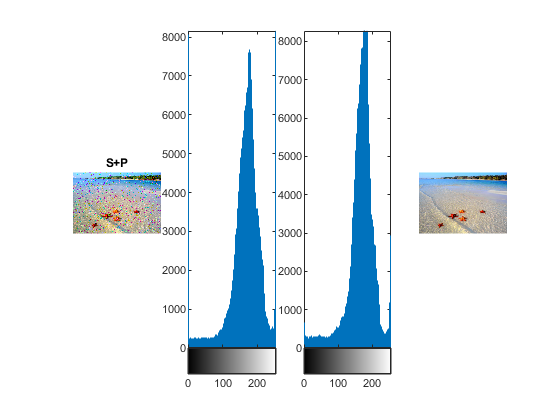


figure
subplot(r,c,1)
imshow(spn)
title("S+P")
subplot(r,c,2)
imhist(spn)
subplot(r,c,3)
imhist(spdn)
subplot(r,c,4)
imshow(spdn)

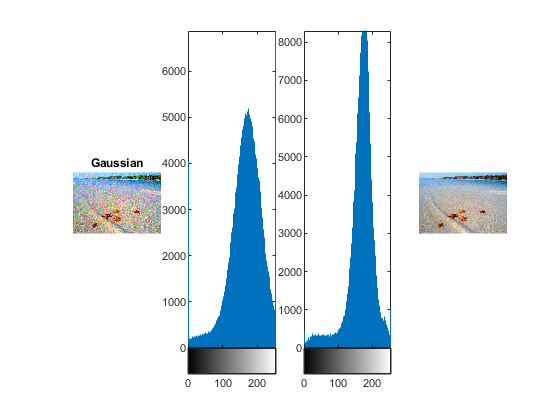


figure
subplot(r,c,1)
imshow(gn)
title("Gaussian")
subplot(r,c,2)
imhist(gn)
subplot(r,c,3)
imhist(gdn)
subplot(r,c,4)
imshow(gdn)

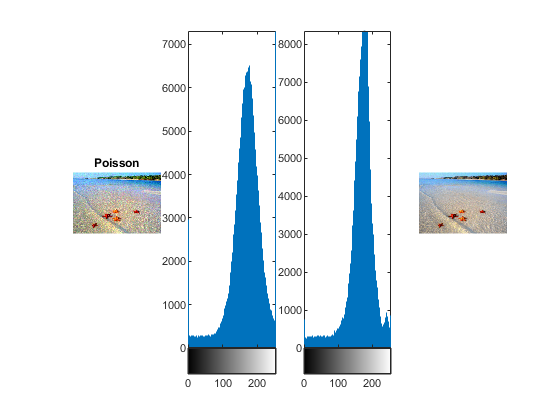


figure
subplot(r,c,1)
imshow(pn)
title("Poisson")
subplot(r,c,2)
imhist(pn)
subplot(r,c,3)
imhist(pdn)
subplot(r,c,4)
imshow(pdn)

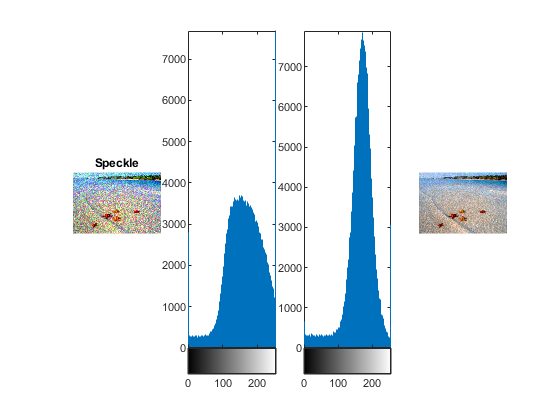


figure
subplot(r,c,1)
imshow(sn)
title("Speckle")
subplot(r,c,2)
imhist(sn)
subplot(r,c,3)
imhist(sdn)
subplot(r,c,4)
imshow(sdn)